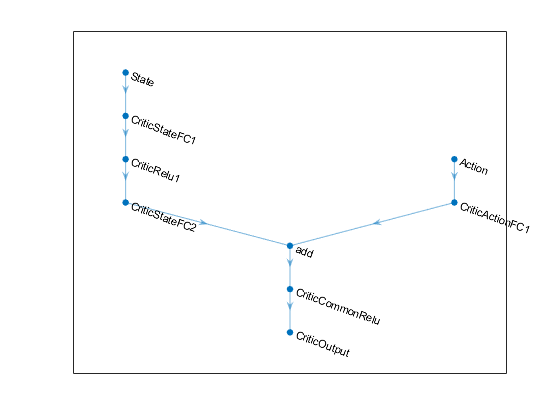

Error using rl.train.seriesTrain (line 16)
An error occurred while simulating "rlpitch2" with the agent "agent".

Error in rl.train.TrainingManager/train (line 251)
                    rl.train.seriesTrain(this);

Error in 

open_system('rlpitch2')
obsInfo = rlNumericSpec([3 1],...
    'LowerLimit',[-inf -inf -inf]',...
    'UpperLimit',[ inf  inf inf]');

numObservations = obsInfo.Dimension(1);

actInfo = rlNumericSpec([3 1]);
numActions = actInfo.Dimension(1);
env = rlSimulinkEnv('rlpitch2','rlpitch2/RL Agent',...
    obsInfo,actInfo);
env.ResetFcn = @(in)localResetFcn(in);
Ts = 1;
Tf = 100;
rng(0)
statePath = [
    imageInputLayer([numObservations 1 1],'Normalization','none','Name','State')
    fullyConnectedLayer(100,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(100,'Name','CriticStateFC2')];
actionPath = [
    imageInputLayer([numActions 1 1],'Normalization','none','Name','Action')
    fullyConnectedLayer(100,'Name','CriticActionFC1')];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');
figure
plot(criticNetwork)
criticOpts = rlRepresentationOptions('LearnRate',1e-04,'GradientThreshold',1);
critic = rlRepresentation(criticNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},criticOpts);

actorNetwork = [
    imageInputLayer([numObservations 1 1],'Normalization','none','Name','State')
    fullyConnectedLayer(100,'Name','ActorFC1')
    reluLayer('Name','ActorRelu1')
    
    fullyConnectedLayer(numActions,'Name','Action')
    ];

actorOptions = rlRepresentationOptions('LearnRate',1e-05,'GradientThreshold',1);

actor = rlRepresentation(actorNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},actorOptions);

agentOpts = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'DiscountFactor',1.0, ...
    'MiniBatchSize',64, ...
    'ExperienceBufferLength',1e6);
agentOpts.NoiseOptions.Variance = 0.3;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;

agent = rlDDPGAgent(actor,critic,agentOpts);

maxepisodes = 10000;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',5, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',Inf);

doTraining = true;

if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load pretrained agent for the example.
    load('WaterTankDDPG.mat','agent')
end


resp={};
tgt=[];
times= {};
val_vals= (-1.5)+1.5*rand(1,10)
for i=1: length(val_vals)
    h = val_vals(i)
    blk = sprintf('rlpitch2/Desired \nPitch Angle');
    set_param(blk,'Value',num2str(h));
    simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');
    experiences = sim(env,agent,simOpts);
    tgt=[tgt experiences.SimulationInfo.Desired];
    resp{end+1}= experiences.SimulationInfo.Actual;
    times{end+1}= experiences.SimulationInfo.tout;
    
end




function in = localResetFcn(in)

% randomize reference signal
blk = sprintf('rlpitch2/Desired \nPitch Angle');

h= (-1.5)+1.5*rand(1,1);
in = setBlockParameter(in,blk,'Value',num2str(h));


end
